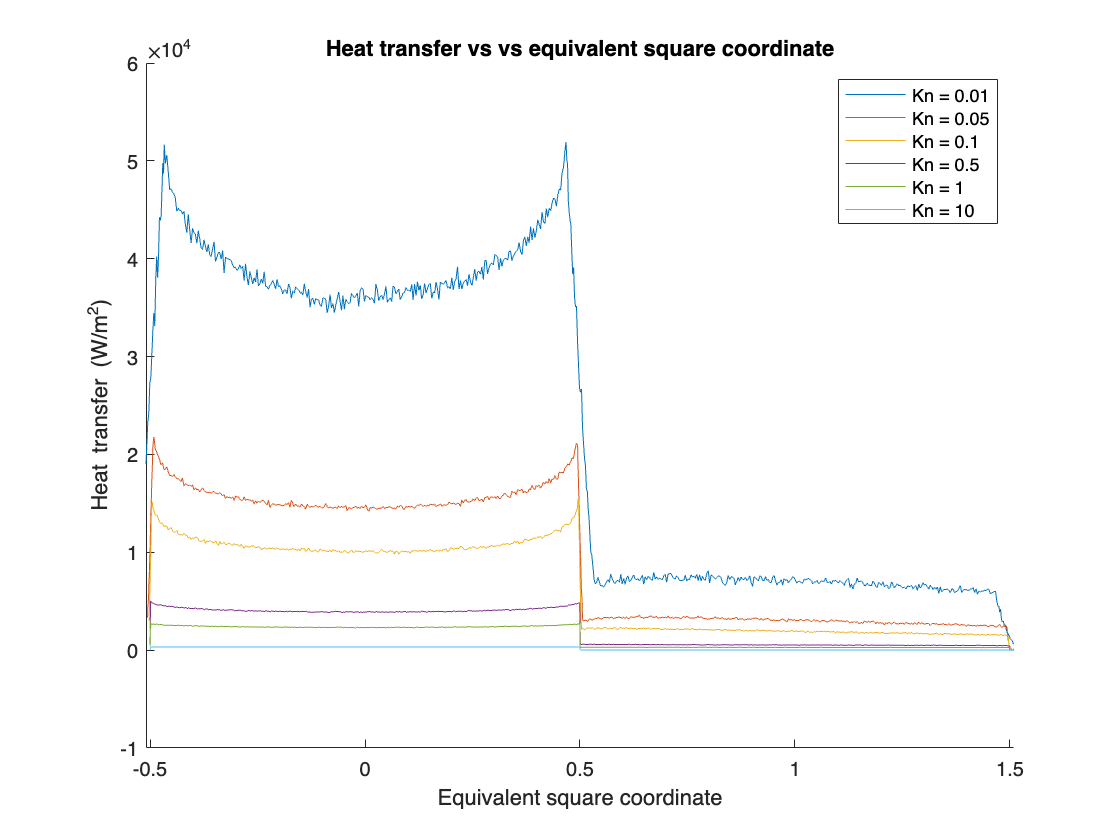

clear

sp=170;
u=1655;
cp=1.4;
tw=300;
t0=273;
H0=cp*t0+u^2/2;
hw=cp*tw;

D001 = readmatrix('./localKn_results/kn0.01.txt');
D001 = sortrows(D001(8:end,1:10),1);
D001(:,11) = D001(:,10)./mean(D001(sp-5:sp+5,10));
rho001=1.727e-4;
D001(:,12) = D001(:,10)./(rho001 * u * (H0 - hw));
D001(:,13:14)=coords('./localKn_results/geometry/r1e-3.txt');

D005 = readmatrix('./localKn_results/kn0.05.txt');
D005 = sortrows(D005(8:end,1:10),1);
D005(:,11) = D005(:,10)./mean(D005(sp-5:sp+5,10));
rho005=3.454e-5;
D005(:,12) = D005(:,10)./(rho005 * u * (H0 - hw));
D005(:,13:14)=coords('./localKn_results/geometry/r2e-4.txt');

D01 = readmatrix('./localKn_results/kn0.1.txt');
D01 = sortrows(D01(8:end,1:10),1);
D01(:,11) = D01(:,10)./mean(D01(sp-5:sp+5,10));
rho01=1.727e-5;
D01(:,12) = D01(:,10)./(rho01 * u * (H0 - hw));
D01(:,13:14)=coords('./localKn_results/geometry/r1e-4.txt');

D05 = readmatrix('./localKn_results/kn0.5.txt');
D05 = sortrows(D05(8:end,1:10),1);
D05(:,11) = D05(:,10)./mean(D05(sp-5:sp+5,10));
rho05=3.454e-6;
D05(:,12) = D05(:,10)./(rho05 * u * (H0 - hw));
D05(:,13:14)=coords('./localKn_results/geometry/r2e-5.txt');

D1 = readmatrix('./localKn_results/kn1.txt');
D1 = sortrows(D1(8:end,1:10),1);
D1(:,11) = D1(:,10)./mean(D1(sp-5:sp+5,10));
rho1=1.727e-6;
D1(:,12) = D1(:,10)./(rho1 * u * (H0 - hw));
D1(:,13:14)=coords('./localKn_results/geometry/r1e-5.txt');

D5 = readmatrix('./localKn_results/kn5.txt');
D5 = sortrows(D5(8:end,1:10),1);
D5(:,11) = D5(:,10)./mean(D5(sp-5:sp+5,10));
rho5=3.454e-7;
D5(:,12) = D5(:,10)./(rho5 * u * (H0 - hw));
D5(:,13:14)=coords('./localKn_results/geometry/r2e-6.txt');

D10 = readmatrix('./localKn_results/kn10.txt');
D10 = sortrows(D10(8:end,1:10),1);
D10(:,11) = D10(:,10)./mean(D10(sp-5:sp+5,10));
rho10=1.727e-7;
D10(:,12) = D10(:,10)./(rho10 * u * (H0 - hw));
D10(:,13:14)=coords('./localKn_results/geometry/r1e-6.txt');

figure
hold on
plot(D001(:,14),D001(:,10))
plot(D005(:,14),D005(:,10))
plot(D01(:,14),D01(:,10))
plot(D05(:,14),D05(:,10))
plot(D1(:,14),D1(:,10))
%plot(D5(:,14),D5(:,10))
plot(D10(:,14),D10(:,10))
legend('Kn = 0.01','Kn = 0.05','Kn = 0.1',...
       'Kn = 0.5','Kn = 1','Kn = 10')
xlabel('Equivalent square coordinate')
ylabel('Heat transfer (W/m^2)')
xlim([-0.51, 1.51])
title('Heat transfer vs vs equivalent square coordinate')

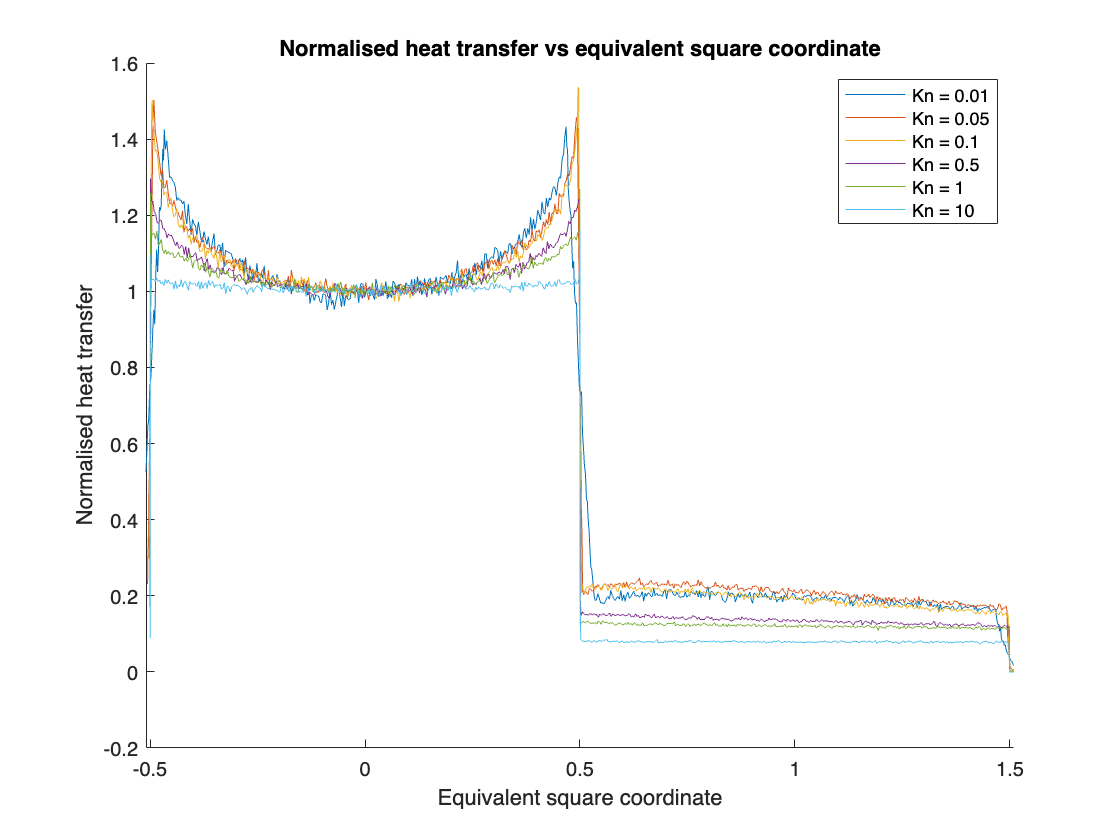


figure
hold on
plot(D001(:,14),D001(:,11))
plot(D005(:,14),D005(:,11))
plot(D01(:,14),D01(:,11))
plot(D05(:,14),D05(:,11))
plot(D1(:,14),D1(:,11))
%plot(D5(:,14),D5(:,11))
plot(D10(:,14),D10(:,11))
legend('Kn = 0.01','Kn = 0.05','Kn = 0.1',...
       'Kn = 0.5','Kn = 1','Kn = 10')
xlabel('Equivalent square coordinate')
ylabel('Normalised heat transfer')
xlim([-0.51, 1.51])
title('Normalised heat transfer vs equivalent square coordinate')

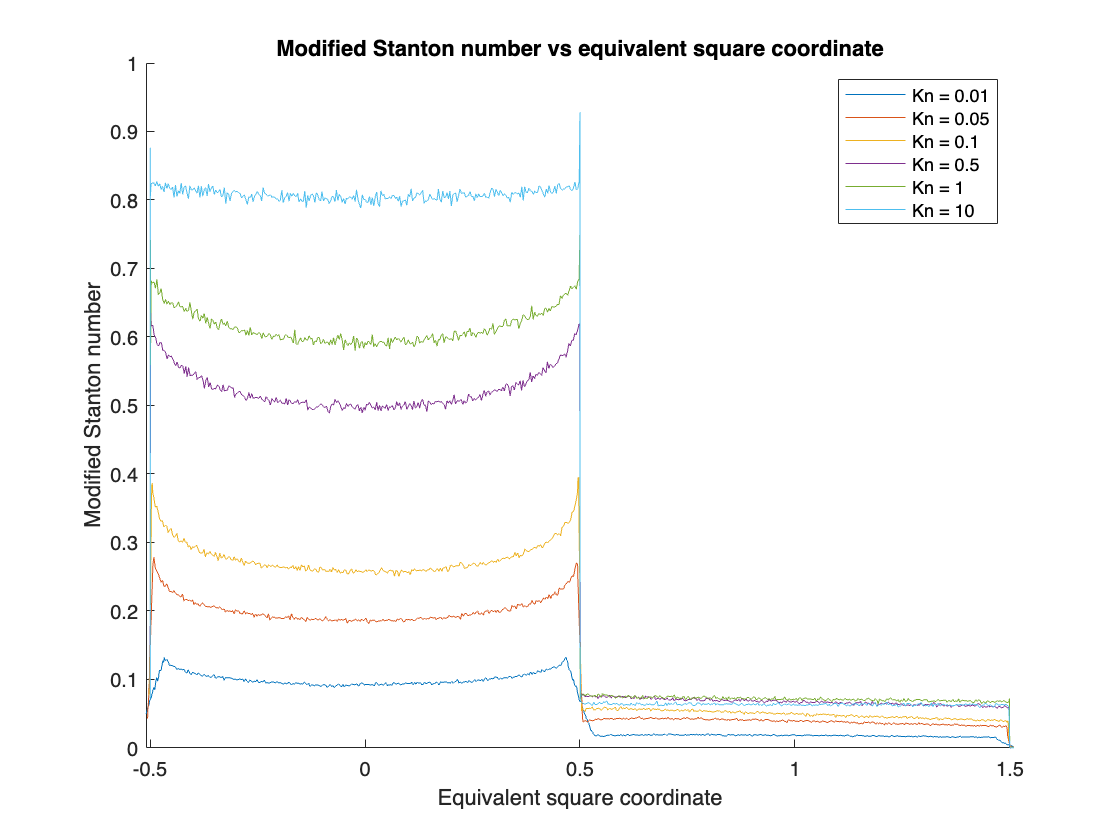


figure
hold on
plot(D001(:,14),D001(:,12))
plot(D005(:,14),D005(:,12))
plot(D01(:,14),D01(:,12))
plot(D05(:,14),D05(:,12))
plot(D1(:,14),D1(:,12))
%plot(D5(:,14),D5(:,12))
plot(D10(:,14),D10(:,12))
legend('Kn = 0.01','Kn = 0.05','Kn = 0.1',...
       'Kn = 0.5','Kn = 1','Kn = 10')
xlabel('Equivalent square coordinate')
ylabel('Modified Stanton number')
xlim([-0.51, 1.51])
title('Modified Stanton number vs equivalent square coordinate')